%%<<<<<<<<<<<<<<<<<<< EIS data >>>>>>>>>>>>>>>>>>>>>
Freq_eis = eisdata(:, 1);
Real_bat_eis = eisdata(:, 2);
Imag_bat_eis = eisdata(:, 3);

% Calculate magnitude and phase
MAG_Z_eis = abs(Real_bat_eis + 1i * Imag_bat_eis);
Phase_Z_eis = angle(Real_bat_eis + 1i * Imag_bat_eis) * 180 / pi;

%%<<<<<<<<<<<<<<< simulation data >>>>>>>>>>>>>>>>>>>>

%%<<<<<<<<<<<<<<< 2500 >>>>>>>>>>>>>>
%setup for FFT
L_sim2500=round(T_sim_2500/Ts_2500)-1;%L_sim2500=20475000
Fs_2500=1/Ts_2500;%Fs_2500=250000
f_b_2500=f_clk_2500/L_MLBS;%f_b_2500=0.611

%FFT for cell voltage & current
FFT_v_sim2500 = fft(out_2500.V_bat.Data, L_sim2500);
FFT_i_sim2500 = fft(-out_2500.I_bat.Data, L_sim2500);

% Initialize arrays to store results
Freq_sim2500 = zeros(1, 1638);
MAG_Z_sim2500 = zeros(1, 1638);
Phase_Z_sim2500 = zeros(1, 1638);
Real_bat_sim2500 = zeros(1, 1638);
Imag_bat_sim2500 = zeros(1, 1638);

% Loop 
k_values_sim2500 = 1:1638;
for idx = 1:length(k_values_sim2500)
    k_sim2500 = k_values_sim2500(idx);
    N_k_sim2500 = round(f_b_2500 * k_sim2500 * L_sim2500 / Fs_2500 + 1);
    Freq_sim2500(idx) = (N_k_sim2500 - 1) * Fs_2500 / L_sim2500;
    %N_k_sim2500=81901;k_sim2500=1639;

    V_k_sim2500 = FFT_v_sim2500(N_k_sim2500);
    I_k_sim2500 = FFT_i_sim2500(N_k_sim2500);

    MagV_k_sim2500 = 2 * abs(V_k_sim2500) / L_sim2500;
    PhaseV_k_sim2500 = angle(V_k_sim2500) * 180 / pi;

    MagI_k_sim2500 = 2 * abs(I_k_sim2500) / L_sim2500;
    PhaseI_k_sim2500 = angle(I_k_sim2500) * 180 / pi;

    Z_k_sim2500 = V_k_sim2500 / I_k_sim2500;
    MAG_Z_sim2500(idx) = abs(Z_k_sim2500);
    Phase_Z_sim2500(idx) = angle(Z_k_sim2500)*180/pi;
    Real_bat_sim2500(idx) = real(Z_k_sim2500);
    Imag_bat_sim2500(idx) = imag(Z_k_sim2500);
end

%%<<<<<<<<<<<<<<< 50 >>>>>>>>>>>>>>
%setup for FFT
L_sim50=round(T_sim_50/Ts_50)-1;
Fs_50=1/Ts_50;
f_b_50=f_clk_50/L_MLBS;

%FFT for cell voltage & current
FFT_v_sim50 = fft(out_50.V_bat.Data, L_sim50);
FFT_i_sim50 = fft(-out_50.I_bat.Data, L_sim50);

% Initialize arrays to store results
Freq_sim50 = zeros(1, 1638);
MAG_Z_sim50 = zeros(1, 1638);
Phase_Z_sim50 = zeros(1, 1638);
Real_bat_sim50 = zeros(1, 1638);
Imag_bat_sim50 = zeros(1, 1638);

% Loop 
%freq from 0.012-20Hz
k_values_sim50 = 1:1638;
for idx = 1:length(k_values_sim50)
    k_sim50 = k_values_sim50(idx);
    N_k_sim50 = round(f_b_50 * k_sim50 * L_sim50 / Fs_50 + 1);
    Freq_sim50(idx) = (N_k_sim50 - 1) * Fs_50 / L_sim50;

    V_k_sim50 = FFT_v_sim50(N_k_sim50);
    I_k_sim50 = FFT_i_sim50(N_k_sim50);

    MagV_k_sim50 = 2 * abs(V_k_sim50) / L_sim50;
    PhaseV_k_sim50 = angle(V_k_sim50) * 180 / pi;

    MagI_k_sim50 = 2 * abs(I_k_sim50) / L_sim50;
    PhaseI_k_sim50 = angle(I_k_sim50) * 180 / pi;

    Z_k_sim50 = V_k_sim50 / I_k_sim50;
    MAG_Z_sim50(idx) = abs(Z_k_sim50);
    Phase_Z_sim50(idx) = angle(Z_k_sim50)*180/pi;
    Real_bat_sim50(idx) = real(Z_k_sim50);
    Imag_bat_sim50(idx) = imag(Z_k_sim50);
end




% simulation data
Real_bat_sim = [Real_bat_sim2500, Real_bat_sim50];
Imag_bat_sim = [Imag_bat_sim2500, Imag_bat_sim50];
MAG_Z_sim = [MAG_Z_sim50, MAG_Z_sim2500];
Phase_Z_sim = [Phase_Z_sim50, Phase_Z_sim2500];
Freq_sim = [Freq_sim50, Freq_sim2500];



%%<<<<<<<<<<<<<<<<<< PRBS data >>>>>>>>>>>>>>>>>>>>>>>
%experiment data
%change file names when use other data
current_I_2500 = -TENo12bitI2500(:, 2);
voltage_V_2500 = TENo12bitV2500(:, 2);

current_I_50 = -TENo12bitI50(:, 2);
voltage_V = TENo12bitV50(:, 2);
%for low clock frequency 
voltage_V_50 = detrend(voltage_V);



%setup for FFT
L_PRBS_2500 = length(current_I_2500); 
L_PRBS_50 = length(current_I_50)

L_PRBS_50 = 250000

N = 12;
L_mlbs = 2^N - 1;


%%<<<<<<<<<<<<<< clock frequency = 2500Hz >>>>>>>>>>>>>>>>>

F_clk_2500 = 2500;
F_b_2500=F_clk_2500/L_mlbs

F_b_2500 = 0.6105

T_S_2500 = 2e-05;%main scale = 500ms
F_S_2500=1/T_S_2500;
 

%FFT for cell voltage & current when f_clk=2500Hz
FFT_v_2500 = fft(voltage_V_2500, L_PRBS_2500);
FFT_i_2500 = fft(current_I_2500, L_PRBS_2500);

% Initialize arrays to store results
Freq_2500 = zeros(1, 1638);
MAG_Z_2500 = zeros(1, 1638);
Phase_Z_2500 = zeros(1, 1638);
Real_bat_2500 = zeros(1, 1638);
Imag_bat_2500 = zeros(1, 1638);

% Loop 
k_values_2500 = 1:1638;
for idx = 1:length(k_values_2500)
    k_2500 = k_values_2500(idx);
    N_k_2500 = round(F_b_2500 * k_2500 * L_PRBS_2500 / F_S_2500 + 1);
    Freq_2500(idx) = (N_k_2500 - 1) * F_S_2500 / L_PRBS_2500;

    V_k_2500 = FFT_v_2500(N_k_2500);
    I_k_2500 = FFT_i_2500(N_k_2500);

    MagV_k_2500 = 2 * abs(V_k_2500) / L_PRBS_2500;
    PhaseV_k_2500 = angle(V_k_2500) * 180 / pi;

    MagI_k_2500 = 2 * abs(I_k_2500) / L_PRBS_2500;
    PhaseI_k_2500 = angle(I_k_2500) * 180 / pi;

    Z_k_2500 = V_k_2500 / I_k_2500;
    MAG_Z_2500(idx) = abs(Z_k_2500);
    Phase_Z_2500(idx) = angle(Z_k_2500)*180/pi;
    Real_bat_2500(idx) = real(Z_k_2500);
    Imag_bat_2500(idx) = imag(Z_k_2500);
end

%%<<<<<<<<< clock frequency = 50Hz >>>>>>>>>>>>>>>

F_clk_50 = 50; 
F_b_50=F_clk_50/L_mlbs

F_b_50 = 0.0122

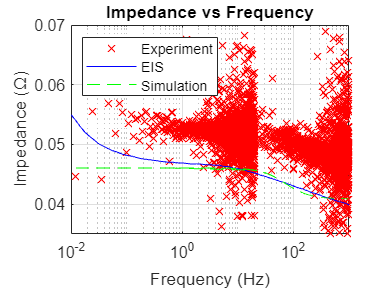

T_S_50 = 2e-03; %main scale = 50ms
F_S_50=1/T_S_50;

%FFT for cell voltage & current when f_clk=50Hz
FFT_v_50 = fft(voltage_V_50, L_PRBS_50);
FFT_i_50 = fft(current_I_50, L_PRBS_50);

% Initialize arrays to store results
Freq_50 = zeros(1, 1638);
MAG_Z_50 = zeros(1, 1638);
Phase_Z_50 = zeros(1, 1638);
Real_bat_50 = zeros(1, 1638);
Imag_bat_50 = zeros(1, 1638);

% Loop through the calculations with k from 1 to 49, step 2
k_values_50 = 1:1638;
for idx = 1:length(k_values_50)
    k_50 = k_values_50(idx);
    N_k_50 = round(F_b_50 * k_50 * L_PRBS_50 / F_S_50 + 1);
    Freq_50(idx) = (N_k_50 - 1) * F_S_50 / L_PRBS_50;

    V_k_50 = FFT_v_50(N_k_50);
    I_k_50 = FFT_i_50(N_k_50);

    MagV_k_50 = 2 * abs(V_k_50) / L_PRBS_50;
    PhaseV_k_50 = angle(V_k_50) * 180 / pi;

    MagI_k_50 = 2 * abs(I_k_50) / L_PRBS_50;
    PhaseI_k_50 = angle(I_k_50) * 180 / pi;

    Z_k_50 = V_k_50 / I_k_50;
    MAG_Z_50(idx) = abs(Z_k_50);
    Phase_Z_50(idx) = angle(Z_k_50)*180/pi;
    Real_bat_50(idx) = real(Z_k_50);
    Imag_bat_50(idx) = imag(Z_k_50);
end


%experiment data

Real_bat = [Real_bat_2500,Real_bat_50];
Imag_bat = [Imag_bat_2500,Imag_bat_50];
MAG_Z = [MAG_Z_50,MAG_Z_2500];
Phase_Z = [Phase_Z_50,Phase_Z_2500];
Freq =  [Freq_50,Freq_2500];


%%<<<<<<<<<<<<<<<< plots >>>>>>>>>>>>>>>>>>>>>>>

%impedence vs frequency plot
figure(1);
semilogx(Freq, MAG_Z, 'rx');
hold on;
semilogx(Freq_eis, MAG_Z_eis, 'b-');
hold on;
semilogx(Freq_sim, MAG_Z_sim, 'g--');

title('Impedance vs Frequency');
xlabel("Frequency (Hz)");
ylabel("Impedance (Ω)");
ylim([0.035, 0.07]);
xlim([0.01, 1000]);
legend('Experiment','EIS','Simulation');
legend('Location','northwest');
grid on;
hold off;

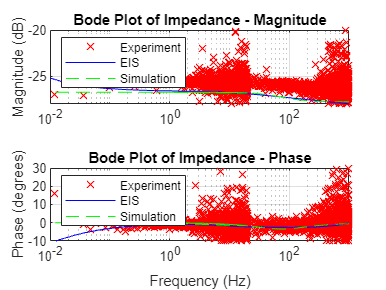


% Bode plot of magnitude and phase
figure(2);

subplot(2, 1, 1);
semilogx(Freq, 20*log10(MAG_Z), 'rx', 'DisplayName', 'Experiment');
hold on;
semilogx(Freq_eis, 20*log10(MAG_Z_eis), 'b-', 'DisplayName', 'EIS');
hold on;
semilogx(Freq_sim, 20*log10(MAG_Z_sim), 'g--', 'DisplayName', 'Simulation');
hold off;
title('Bode Plot of Impedance - Magnitude');
ylim([-28, -20]);
% xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0.01, 1000]);
legend('Location','northwest');
legend show;
grid on;

subplot(2, 1, 2);
semilogx(Freq, Phase_Z, 'rx', 'DisplayName', 'Experiment');
hold on;
semilogx(Freq_eis, Phase_Z_eis, 'b-', 'DisplayName', 'EIS');
hold on;
semilogx(Freq_sim, Phase_Z_sim, 'g--', 'DisplayName', 'Simulation');
hold off;
title('Bode Plot of Impedance - Phase');
ylim([-10, 30]);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
xlim([0.01, 1000]);
legend('Location','northwest');
legend show;
grid on;

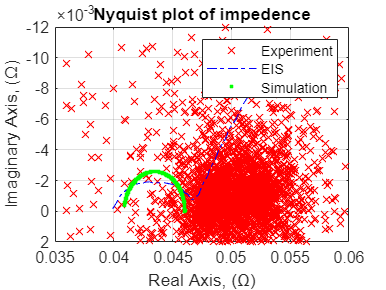




%Nyquist plot based on battery ECM parameters

figure(3);
plot(Real_bat, Imag_bat, 'rx');
hold on;
plot(Real_bat_eis, Imag_bat_eis, 'b-.');
hold on;
plot(Real_bat_sim, Imag_bat_sim, 'g.');
title('Nyquist plot of impedence');
xlabel("Real Axis, (Ω)");
ylabel("Imaginary Axis, (Ω)");
xlim([0.035, 0.06]);
ylim([-12e-3, 2e-3]);
set(gca,'ydir','reverse');
legend('Experiment','EIS','Simulation');
grid on;

hold off;